# Converting Between Color Spaces

clc;            % Clear command window
clear;          % Remove all workspace variables
close all;      % Close all open figures

### Import and display a color image

Run this section to read in an image of peppers.

imgRGB = imread('peppers.png');   
imshow(imgRGB);            

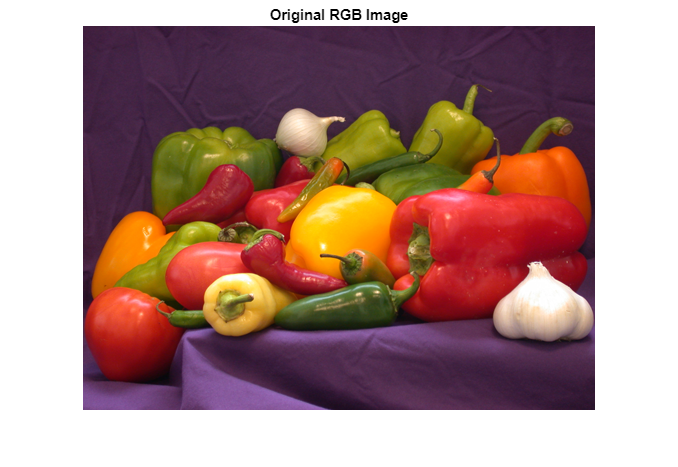

title('Original RGB Image');

### Convert to alternative color spaces

Uncomment the lines of code below and convert the image to alternative color spaces. Use the variable names provided as they will be used in the rest of this script.

Convert to HSV

hsvImg = rgb2hsv(imgRGB) 

hsvImg = hsvImg(:,:,1) =

    0.8238    0.8283    0.8278    0.8571    0.8632    0.8385    0.8280    0.8434    0.8535    0.8636    0.8480    0.8495    0.8762    0.8594    0.8444    0.8438    0.8384    0.8384    0.8535    0.8619    0.8542    0.8725    0.8657    0.8480    0.8565    0.8542    0.8333    0.8438    0.8448    0.8333    0.8514    0.8434    0.8547    0.8632    0.8596    0.8426    0.8381    0.8559    0.8559    0.8382    0.8333    0.8529    0.8524    0.8465    0.8504    0.8333    0.8429    0.8571    0.8535    0.8429    0.8382    0.8438    0.8485    0.8495    0.8490    0.8476    0.8547    0.8524    0.8529    0.8429    0.8480    0.8571    0.8529    0.8434    0.8429    0.8514    0.8571    0.8438    0.8280    0.8565    0.8468    0.8148    0.8278    0.8333    0.8229    0.8267    0.8086    0.8167    0.8506    0.8278    0.8222    0.8276    0.8194    0.8472    0.8690    0.8563    0.8444    0.8441    0.8333    0.8490    0.8393    0.8333    0.8438    0.8380    0.8288    0.8283    0.8431    

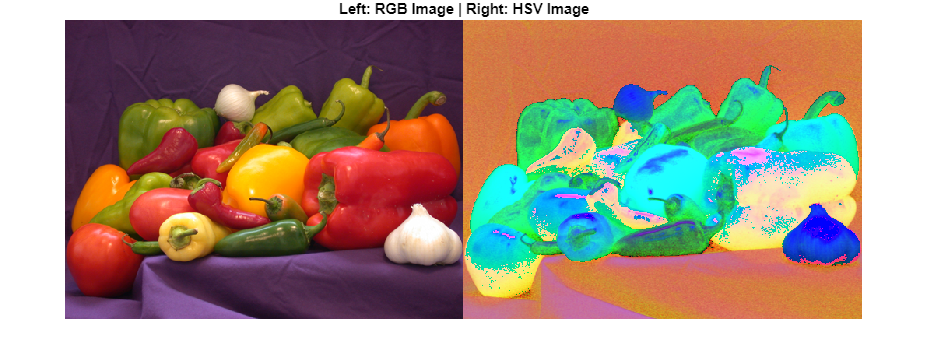

montage({imgRGB, hsvImg});         % Side-by-side display
title('Left: RGB Image | Right: HSV Image');

Convert to YCbCr

ycbcrImg = rgb2ycbcr(imgRGB)

ycbcrImg = 384×512×3 uint8 array
ycbcrImg(:,:,1) =

    53    54    56    54    52    54    53    53    53    54    54    52    53    54    53    53    53    55    55    53    52    53    53    54    54    56    56    55    56    54    55    58    56    56    57    58    57    60    60    59    59    59    59    58    60    58    57    58    57    56    56    59    58    57    57    56    57    58    58    56    57    59    58    59    59    58    59    60    59    56    55    52    50    48    45    44    43    46    47    48    49    52    51    50    50    51    52    52    51    50    51    52    54    55    58    59    59    60    59    59    58    58    59    58    55    54    55    56    55    56    56    56    56    57    57    55    54    56    56    55    56    57    54    55    56    54    55    55    55    54    53    54    55    56    56    57    59    59    57    55    56    59    59    59    59    60    59    58    58    58    60    60    59    61    59    60    60    59

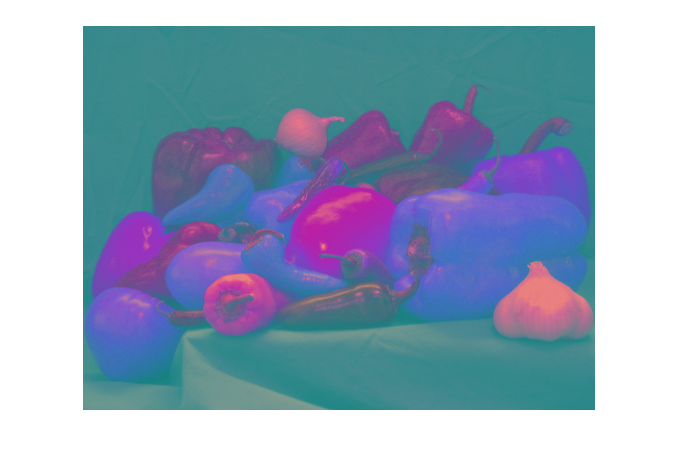

imshow(ycbcrImg)

Convert to L*a*b*

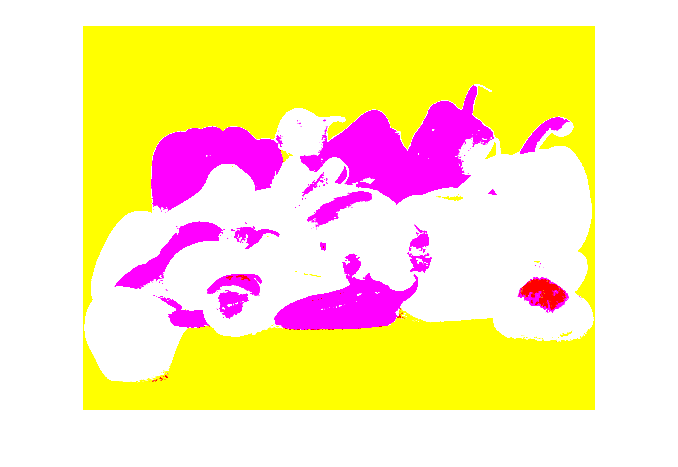

labImg = rgb2lab(imgRGB);
imshow(labImg)

Notice how the original image and the YCbCr representation are both of type uint8, but the HSV and L*a*b* values are of type double. This is important to remember as you perform your own color space conversions.

## `Extract and Visualize Hue Channel` 

The code below extracts the values at the top left hand corner of the third color plane for all four images. Examine the results. 

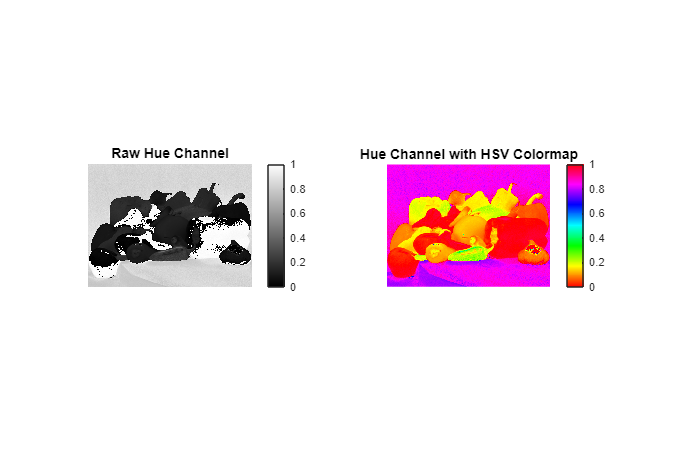

hueChannel = hsvImg(:,:,1);        % Extract Hue component (range 0-1)

subplot(1,2,1);
imshow(hueChannel);                % Display raw hue values
title('Raw Hue Channel');
colorbar;                          % Show color scale

subplot(1,2,2);
imshow(hueChannel);                % Display with HSV colormap
colormap(gca, hsv);                % Apply hue-color mapping
colorbar;
title('Hue Channel with HSV Colormap');

#### `Create Color Range Mask`

`Target hue range: 0.8-0.9 (corresponds to blue-cyan colors in HSV wheel)`

hueMask = (hueChannel > 0.8) & (hueChannel < 0.9);

`Invert mask to select NON-target `

areashueMask = ~hueMask;

`show the mask:`

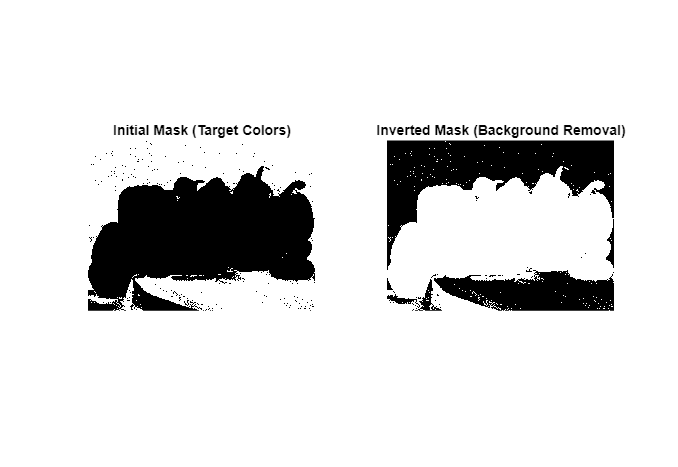

subplot(1,2,1);
imshow(hueMask);                   % Show initial mask
title('Initial Mask (Target Colors)');


subplot(1,2,2);
imshow(areashueMask);                   % Show inverted mask
title('Inverted Mask (Background Removal)');

#### `Apply Mask to Original Image` 

`Convert logical mask to uint8 (0-255), it is needed for multiplication later.`

mask3D = uint8(areashueMask);

Apply mask using element-wise multiplication

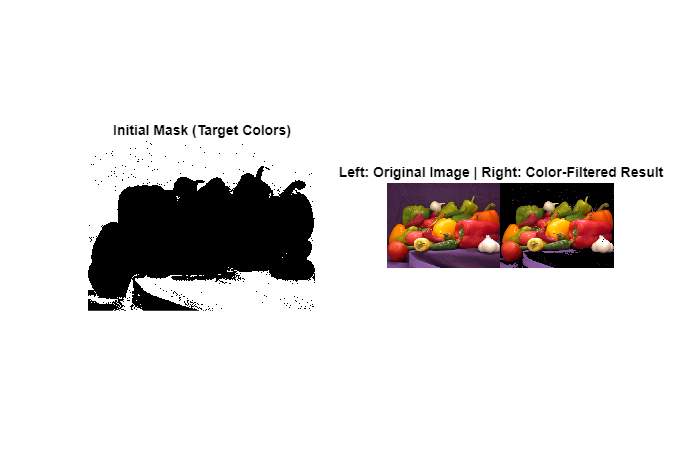

filteredImg = imgRGB .* mask3D;

montage({imgRGB, filteredImg});
title('Left: Original Image | Right: Color-Filtered Result');

### Display the image correctly in RGB

The `imshow` function only interprets images in the RGB color space. It does, however, accept matrices of different data types, including both uint8 and double, which is why we were able to run `imshow` with the HSV and L*a*b* images. 

*Always convert back to RGB* when working with images in different color spaces before displaying them.

Uncomment the lines below to convert the images back to RGB.

Convert from HSV to RGB

rgbImg1 = hsv2rgb(hsvImg)

Convert from YCbCr to RGB

rgbImg2 = ycbcr2rgb(ycbcrImg)

Convert from L*a*b* to RGB

rgbImg3 = lab2rgb(labImg) 

Display the images again.

imshow(rgbImg1)
imshow(rgbImg2)
imshow(rgbImg3)

That's much better! All of these images look identical to the original image. Do note that changing the images back to RGB does not change their datatypes, so two of the three new RGB images are of type double. 

Notice how the original image and the YCbCr representation are both of type uint8, but the HSV and L*a*b* values are of type double. This is important to remember as you perform your own color space conversions.